## **Relatório Matemática Computacional**

close all
clear all
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(x-1).*x.^2-2.*x-exp(x-1)+2;
d2f = @(x) exp(x-1).*x.^2+2.*exp(x-1).*x-exp(x-1)-2;
d3f = @(x) exp(x-1).*x.^2+4.*exp(x-1).*x+exp(x-1);
J = [0,3/2];

### **a)**

a = 1/10;
I = [0,0.7];

Para provar a convergência do método de Newton as condições do Critério 1 têm de ser verificadas.

Sendo f uma função C^2 :

1) f(a)f(b)<0 (existência de raíz)

f(I(1),a).*f(I(2),a) < 0

ans = logical
   1


2) f'(x)!=0 para qualquer x pertencente ao intervalo I (unicidade da raíz)

d1f(I(1)).*d1f(I(2)) > 0

ans = logical
   1


3) f''(x)>=0 ou f''(x)<=0 para qualquer x pertencente ao intervalo I (não muda o sentido da concavidade)

exp(x-1).*x.^2+2.*exp(x-1).*x-exp(x-1)-2 < 0 para qualquer x pertencente ao intervalo I

4)

abs(f(I(1),a))./abs(d1f(I(1))) < I(2)-I(1)

ans = logical
   1


abs(f(I(2),a))./abs(d1f(I(2))) < I(2)-I(1)

ans = logical
   1


Demonstrou-se assim que para a sucessão dada pelo método de Newton, esta é convergente para z, qualquer que seja a iterada inicial x0 ∈ [0, 0.7], sendo esta raíz única.

### b)

#### Considerando a = 1/10, x0 = 0.3, N = 25 e $\epsilon ={10}^{-12}$

format LongE
r = real_zero(1/10,0.3);
fprintf('O zero real é: %i',r)

O zero real é: 4.970199e-01

[rbar,k] = newton_method(a,0.3,25, 10.^(-12));
fprintf("A raíz é: %i\n",rbar(end))

A raíz é: 4.970199e-01


fprintf("A iteração é: %i",k)

A iteração é: 6

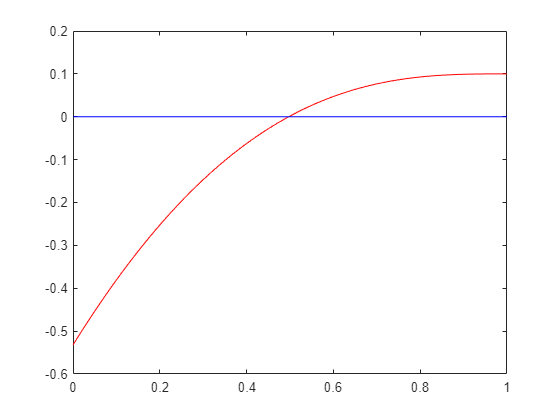


%Representação gráfica
s=0:0.01:1;
plot(s,((s-1).^2).*(exp(s-1)-1)+a,"Color",'r')
hold on
yy=zeros(1,length(s));
plot(s,yy,'Color','b')
hold off


iteracoes = [rbar]

iteracoes =      3.000000000000000e-01     4.547010446644338e-01     4.943124381545204e-01     4.970076637293769e-01     4.970199177410525e-01     4.970199179938893e-01     4.970199179938894e-01


### c)

M=41;
a_i = linspace(-1/10,1/10,M);
ga = [];
kga = [];
for i = 1:1:numberofelements(a_i)
    [rbar,k] = newton_method(a_i(i),0.9,25,10.^(-7));
    ga(end+1) = rbar(end);
    kga(end+1) = k;
end

#### i)

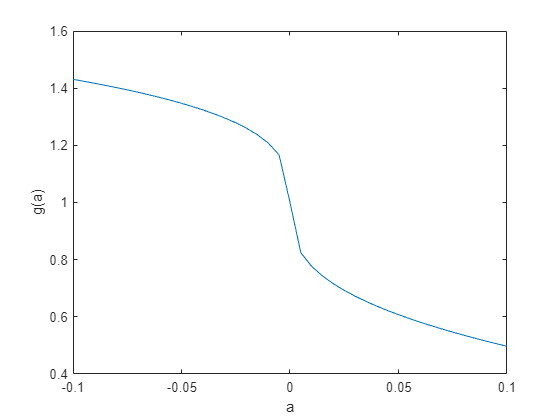

plot(a_i,ga)
xlabel('a')
ylabel('g(a)')

#### ii)

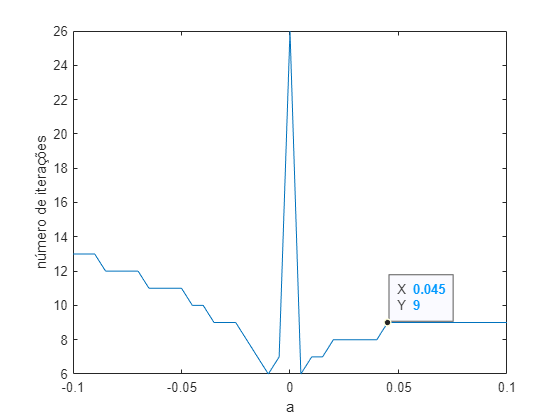

plot(a_i,kga)
xlabel('a')
ylabel('número de iterações')

fazer tabela

format short
[~,k1] = newton_method(-0.1,0.9,25,10.^(-7));
[~,k2] = newton_method(-0.05,0.9,25,10.^(-7));
[~,k3] = newton_method(0,0.9,25,10.^(-7));
[~,k4] = newton_method(0.05,0.9,25,10.^(-7));
[~,k5] = newton_method(0.1,0.9,25,10.^(-7));
[-0.01 -0.05 0 0.05 0.01; k1 k2 k3 k4 k5]

ans =    -0.0100   -0.0500         0    0.0500    0.0100
   13.0000   11.0000   26.0000    9.0000    9.0000


### d)

Através da visualização gráfica verificamos que para um determinado *a* a função f(a) tem um zero múltiplo.

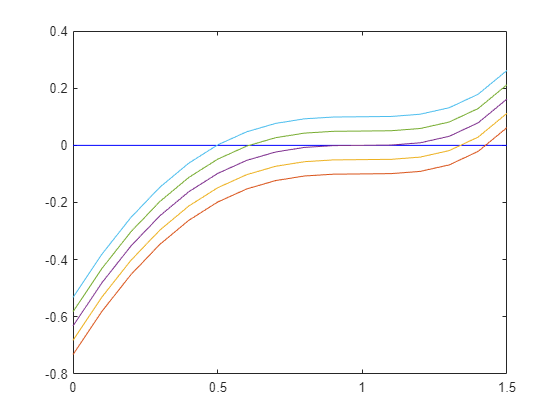

x = J(1):0.1:J(2);
yy=zeros(1,length(x));
plot(x,yy,'Color','b')
hold on
for  i = -1/10:0.05:1/10
    plot(x,f(x,i))
    %pause(0.5)
end
hold off

O zero múltiplo dá-se no caso em que no zero da função a sua respetiva derivada também é zero. Isso acontece quando a = 0 

Pelo gráfico apresentado na alínea anterior percebemos que o Método de Newton não funciona tão bem para estes casos uma vez que se destaca um pico no número de iterações em a = 0.

### e)

#### Caso a = 1/10, dada uma iterada x0

format long
a = 1/10;
x0 = 0.3;
k = 4;

r = real_zero(a,x0)

r =    0.497019917993889



%iteradas (k)
res = [x0];
for i = 1:1:k
    [v,~] = newton_method(a,x0,i,10.^(-12));
    res = [res, v(end)];
end
res

res =    0.300000000000000   0.454701044664434   0.494312438154520   0.497007663729377   0.497019917741053



%erros
erro = [];
for i = 1:1:k+1
    erro = [erro, r-res(i)];
end
erro

erro =    0.197019917993889   0.042318873329456   0.002707479839369   0.000012254264512   0.000000000252837


Experimentar convergência linear p = 1:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^1];
end
K   

K =    0.214794898710536   0.063978069980526   0.004526077843393   0.000020632556674


Vemos que os rácios não se aproximam de uma constante positiva de uma forma saudável, sendo possível concluir que p ≠ 1 

Experimentar convergência quadrática p = 2:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^2];
end
K

K =    1.090219206756536   1.511809387798488   1.671694015069053   1.683704203773818


Desta vez, podemos ver que o rácio tende monotonamente para algo como 1.69, sendo então possível estimar que a ordem de convergência p = 2 e K = 1.69

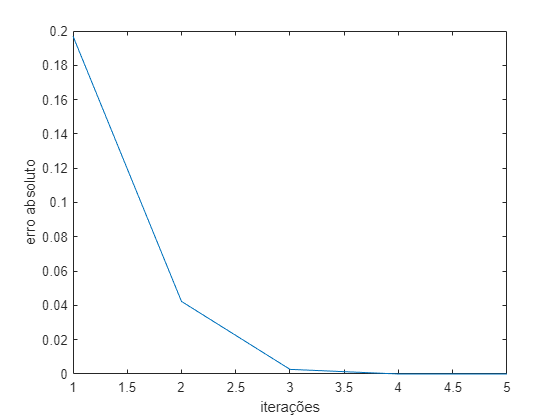

%Desenhar gráfico do erro absoluto em função das iterações
x = 1:1:k+1;
plot(x,erro)
xlabel('iterações')
ylabel('erro absoluto')

#### Caso a = 0, dada uma iteração x0

a = 0;
x0 = 0.3;
k = 26;

r = real_zero(a,x0)

r =      1



%iteradas (k)
res = [x0];
for i = 1:1:k
    [v,~] = newton_method(a,x0,i,10.^(-12));
    res = [res, v(end)];
end
res

res =    0.300000000000000   0.560174330486048   0.717470873509472   0.816071853050953   0.879258869826157   0.920315495011559   0.947229690823826   0.964974487737426   0.976717810969820   0.984508654654968   0.989685768668822   0.993129755948847   0.995422459532087   0.996949470458313   0.997966830623768   0.998644783403460   0.999096624302967   0.999397794873506   0.999598550062956   0.999732375662121   0.999821587753820   0.999881060270869   0.999920707633188   0.999947138771331   0.999964759335749   0.999976506292553   0.999984337559663



%erros
erro = [];
for i = 1:1:k+1
    erro = [erro, r-res(i)];
end
erro

erro =    0.700000000000000   0.439825669513952   0.282529126490528   0.183928146949047   0.120741130173843   0.079684504988441   0.052770309176174   0.035025512262574   0.023282189030180   0.015491345345032   0.010314231331178   0.006870244051153   0.004577540467913   0.003050529541687   0.002033169376232   0.001355216596540   0.000903375697033   0.000602205126494   0.000401449937044   0.000267624337879   0.000178412246180   0.000118939729131   0.000079292366812   0.000052861228669   0.000035240664251   0.000023493707447   0.000015662440337


Experimentar convergência linear p = 1:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^1];
end
K

K =    0.628322385019931   0.642366160216954   0.651005966123684   0.656458145078206   0.659961563004352   0.662240534515827   0.663735210374464   0.664720871336347   0.665373231226299   0.665806042112742   0.666093655509324   0.666284986942332   0.666412359010352   0.666497192847153   0.666553712830260   0.666591376861007   0.666616479137725   0.666633210814859   0.666644363802633   0.666651798538900   0.666656755224216   0.666660058763606   0.666662262649290   0.666663737074072   0.666664716642677   0.666665334648657


Neste caso, os rácios tendem perfeitamente para cerca de 0.666, podendo este último ser, então, o valor de K e a ordem de convergência p = 1.

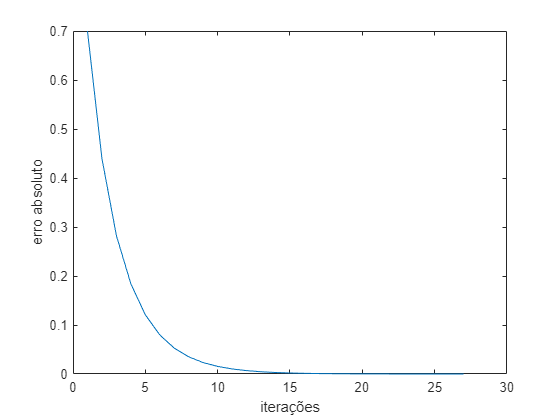

%Desenhar gráfico do erro absoluto em função das iterações
x = 1:1:k+1;
plot(x,erro)
xlabel('iterações')
ylabel('erro absoluto')

### f)

No que diz respeito à alínea e), em ambos os casos (a = 1/10 e a = 0) a ordem de convergência foi a esperada/prevista. 

Para a = 1/10, verificámos que a primeira e a segunda derivadas de f em r são diferentes de 0:

a = 1/10;
x0 = 0.3;
k = 4;
r = real_zero(a,x0)

r =    0.497019917993889


d1f(r)

ans =    0.550619022523299


d2f(r)

ans =   -1.854219567473244


logo, a ordem de convergência prevista seria 2, tal como foi obtido experimentalmente.

Da mesma forma, para a = 0, concluímos *a priori* que a primeira derivada de f em r é igual a 0:

a = 0;
x0 = 0.3;
k = 4;
r = real_zero(a,x0)

r =      1


d1f(r)

ans =      0


sendo logo possível assumir que a ordem de convergência seria 1, tal como foi obtido experimentalmente, de novo.

Na alínea e) comprovámos os resultados esperados à priori, concluindo que a ordem de convergência quando a = 1/10 (p=2) seria maior do que em a = 0 (p=1).

Partindo do princípio de que a ordem de convergência traduz a rapidez de como o metodo chega a uma aproximação da raíz, é possível prever que quanto maior p, mais rapidamente o metodo converge, logo menos iteradas serão necessárias para a mesma aproximação, tal como se regista no gráfico da alínea c) em que para a = 1/10 temos 9 iteradas em comparação com a = 0 em que se registam 26 iteradas, o que comprova o que foi anteriormente dito.

### Definição de Funções

%Função do Método de Newton
function [rbar,k] = newton_method(a,x0,nmax,epsilon)
nmax = nmax+1;
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(x-1).*x.^2-2.*x-exp(x-1)+2;
x=[x0];
k=1;
while k<nmax
    x(k+1)= x(k)-f(x(k),a)./d1f(x(k));
    if abs(x(k+1)-x(k)) < epsilon;
        break
    end
    k=k+1;
end
rbar = x;
end

%Função do zero real
function [r] = real_zero(a,x0)
g = @(x)((x-1).^2).*(exp(x-1)-1)+a;
r = fzero(g,x0);
end